# OGLO notebook 2

hnxj@github

## 1: AAAB vs BBBA (trial PEV)

AAAB vs BBBA (Hp: hierarchical difference in stim selectivity)

cond1 = 1; % AAAB
cond2 = 5; % BBBA

% expvars = cell(1, 10);

for k = 5:10

    ntotal = 0;
    expvars{k} = zeros(areaCounts(k), 5000);
    disp(k);

    for l = 1:size(z{k}{1}, 2)

        x1 = z{k}{cond1}{l}(:, :, 1:5000);
        x2 = z{k}{cond2}{l}(:, :, 1:5000);
        
        N = min(size(x1, 1), size(x2, 1));
        n1 = size(x1, 2);
    
        idx1 = randperm(size(x1, 1), N);
        idx2 = randperm(size(x2, 1), N);
        
        % x1 = squeeze(mean(x1(idx1, :, :), 1));
        % x2 = squeeze(mean(x2(idx2, :, :), 1));
        x1 = x1(idx1, :, :);
        x2 = x2(idx2, :, :);
        
        if n1 > 0 && N > 0

            data = zeros(N*2, n1, 5000);
            data(1:N, :, :) = x1;
            data(N+1:end, :, :) = x2;
            data = jSmooth(data, 100);
    
            groupIDs = [ones(1, N), ones(1, N)*2];
            [expv, n, mu, p, F] = jPEV(data, groupIDs, 1);
            expvars{k}(ntotal+1:ntotal+n1, :) = squeeze(expv);

        end

        ntotal = n1 + ntotal;

    end

end

     5

     6

     7

     8

     9

    10



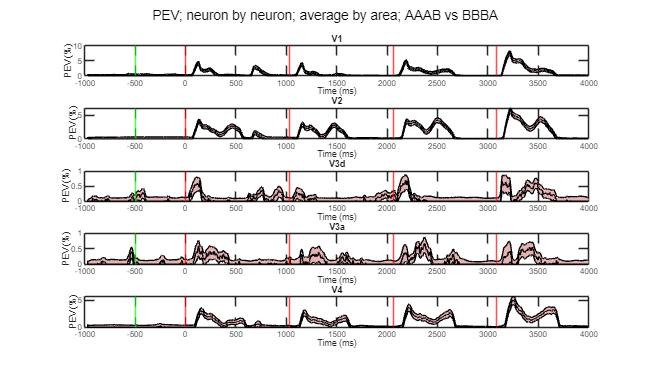

figure("Position", [0 0 2000 1000]);
cl = [0.9 0.7 0.7];

for k = 1:5

    subplot(5, 1, mod(k-1, 5)+1);
    ths = median(mean(expvars{k}, 2));
    idxp = mean(expvars{k}, 2) > ths;
    % figure("Position", [0 0 1500 500]);
    t = linspace(-970, 4030, 5000);
    yt = detrend(squeeze(mean(expvars{k}(idxp, :), 1)))'*100;
    yt(yt<0) = 0;
    st = smooth(squeeze(std(expvars{k}(idxp, :), 1)), 50)*100/sqrt(areaCounts(k));
    stx = smooth(yt + st, 20);stx(stx<0) = 0;
    sty = smooth(yt - st, 20);sty(sty<0) = 0;
    plot(t, stx, "Color", cl);
    hold("on");
    plot(t, sty, "Color", cl);
    patch([t, t(end:-1:1)], [stx;sty(end:-1:1)], cl);
    plot(t, yt, "Color", "k");

    xline(-500, "HandleVisibility", "off", "Color", "g");
    xline(0, "HandleVisibility", "off", "Color", "r");
    xline(1030, "HandleVisibility", "off", "Color", "r");
    xline(2060, "HandleVisibility", "off", "Color", "r");
    xline(3090, "HandleVisibility", "off", "Color", "r");

    title(areaNames{k});
    xlabel("Time (ms)");
    ylabel("PEV (%)");
    xlim([-1000 4000]);

end
sgtitle("PEV; neuron by neuron; average by area; AAAB vs BBBA");
fname = num2str(k) + "_abpev";
print(gcf,'-vector','-dsvg',fname +".svg");

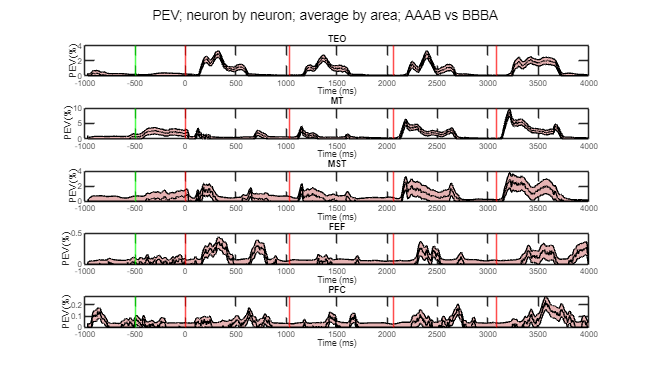

figure("Position", [0 0 2000 1000]);
cl = [0.9 0.7 0.7];

for k = 6:10

    subplot(5, 1, mod(k-1, 5)+1);
    ths = median(mean(expvars{k}, 2));
    idxp = mean(expvars{k}, 2) > ths;
    % figure("Position", [0 0 1500 500]);
    t = linspace(-970, 4030, 5000);
    yt = detrend(squeeze(mean(expvars{k}(idxp, :), 1)))'*100;
    yt(yt<0) = 0;
    st = smooth(squeeze(std(expvars{k}(idxp, :), 1)), 50)*100/sqrt(areaCounts(k));
    stx = smooth(yt + st, 20);stx(stx<0) = 0;
    sty = smooth(yt - st, 20);sty(sty<0) = 0;
    plot(t, stx, "Color", cl);
    hold("on");
    plot(t, sty, "Color", cl);
    patch([t, t(end:-1:1)], [stx;sty(end:-1:1)], cl);
    plot(t, yt, "Color", "k");

    xline(-500, "HandleVisibility", "off", "Color", "g");
    xline(0, "HandleVisibility", "off", "Color", "r");
    xline(1030, "HandleVisibility", "off", "Color", "r");
    xline(2060, "HandleVisibility", "off", "Color", "r");
    xline(3090, "HandleVisibility", "off", "Color", "r");

    title(areaNames{k});
    xlabel("Time (ms)");
    ylabel("PEV (%)");
    xlim([-1000 4000]);

end
sgtitle("PEV; neuron by neuron; average by area; AAAB vs BBBA");
fname = num2str(k) + "_abpev";
print(gcf,'-vector','-dsvg',fname +".svg");

## 2: Any omission PEV

AAAB vs BBBA (Hp: hierarchical difference in stim selectivity)

aaab = 1;
axab = 2;
aaxb = 3;
aaax = 4;
bbba = 5;
bxba = 6;
bbxa = 7;
bbbx = 8;
rrrr = 9;
rxrr = 10;
rrxr = 11;
rrrx = 12;

expvarx = cell(1, 10);

for k = 1:10

    ntotal = 0;
    expvarx{k} = zeros(areaCounts(k), 1000);
    disp(k);

    for l = 1:size(z{k}{1}, 2)

        x1 = z{k}{rrrx}{l}(:, :, 4001:5000);
        x2 = z{k}{aaax}{l}(:, :, 4001:5000);
        x3 = z{k}{bbbx}{l}(:, :, 4001:5000);
        
        N = min([size(x1, 1), size(x2, 1), size(x3, 1)]);
        n1 = size(x1, 2);
    
        idx1 = randperm(size(x1, 1), N);
        idx2 = randperm(size(x2, 1), N);
        idx3 = randperm(size(x3, 1), N);

        x1 = x1(idx1, :, :);
        x2 = x2(idx2, :, :);
        x3 = x3(idx3, :, :);
        
        if n1 > 0 && N > 0

            data = zeros(N*3, n1, 1000);
            data(1:N, :, :) = x1;
            data(N+1:2*N, :, :) = x2;
            data(2*N+1:end, :, :) = x3;

            data = jSmooth(data, 100);
            % data(:, :, 1:500) = data(:, :, randperm(500, 500));
    
            groupIDs = [ones(1, N), ones(1, N)*2, ones(1, N)*3];
            [expv, n, mu, p, F] = jPEV(data, groupIDs, 1);
            expvarx{k}(ntotal+1:ntotal+n1, :) = squeeze(expv);

        end

        ntotal = n1 + ntotal;

    end

end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10



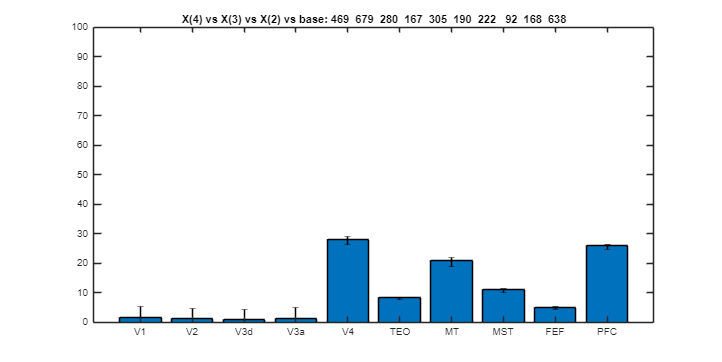

figure("Position", [0 0 2000 1000]);
cl = [0.9 0.1 0.1];
yt = zeros(1, 10);
st = zeros(1, 10);

for k = 1:10

    ths = median(mean(expvarx{k}, 2))*0;
    idxp = mean(expvarx{k}, 2) > ths;
    t = linspace(-500, 1000, 1500);
    yt(k) = (mean(abs(max(expvarx{k}(idxp, :) - 0.9*mean(expvarx{k}(idxp, :), 'all')))) - 1.01*min(abs(max(expvarx{k}(idxp, :) - mean(expvarx{k}(idxp, :), 'all')))))*100;
    st(k) = mean(std(expvarx{k}(idxp, :)))*100 / sqrt(min(100, sum(idxp)));
    
end

bar(areaNames, yt);                

hold on

er = errorbar(categorical(areaNames),yt,2*st,st);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';  
ylim([0 100]);

hold off
title("X(4) vs X(3) vs X(2) vs base: " + num2str(areaCounts));

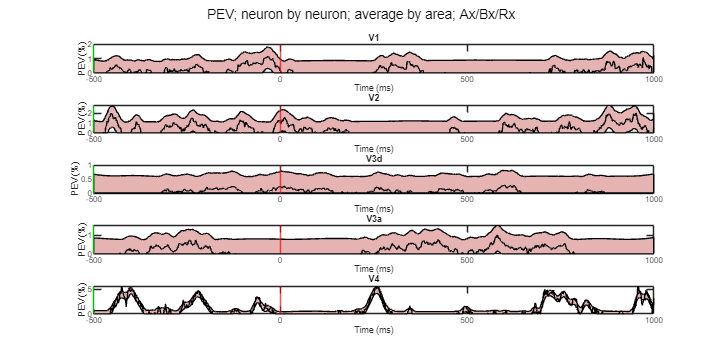

figure("Position", [0 0 2000 1000]);
cl = [0.9 0.7 0.7];

for k = 1:5

    subplot(5, 1, mod(k-1, 5)+1);
    ths = median(mean(expvarx{k}, 2))*4;
    idxp = mean(expvarx{k}, 2) > ths;
    % figure("Position", [0 0 1500 500]);
    t = linspace(-500, 1000, 1500);
    yt = detrend(squeeze(mean(expvarx{k}(idxp, :), 1)))'*100;
    yt(yt<0) = 0;
    st = smooth(squeeze(std(expvarx{k}(idxp, :), 1)), 50)*100/sqrt(1000);
    stx = smooth(yt + st, 20);stx(stx<0) = 0;
    sty = smooth(yt - st, 20);sty(sty<0) = 0;
    plot(t, stx, "Color", cl);
    hold("on");
    plot(t, sty, "Color", cl);
    patch([t, t(end:-1:1)], [stx;sty(end:-1:1)], cl);
    plot(t, yt, "Color", "k");

    xline(-500, "HandleVisibility", "off", "Color", "g");
    xline(0, "HandleVisibility", "off", "Color", "r");
    xline(1030, "HandleVisibility", "off", "Color", "r");
    xline(2060, "HandleVisibility", "off", "Color", "r");
    xline(3090, "HandleVisibility", "off", "Color", "r");

    title(areaNames{k});
    xlabel("Time (ms)");
    ylabel("PEV (%)");
    xlim([-500 1000]);

end
sgtitle("PEV; neuron by neuron; average by area; Ax/Bx/Rx");

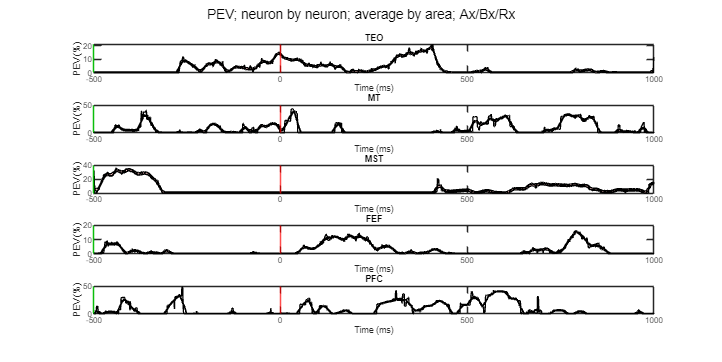

figure("Position", [0 0 2000 1000]);
cl = [0.9 0.7 0.7];

for k = 6:10

    subplot(5, 1, mod(k-1, 5)+1);
    ths = max(mean(expvarx{k}, 2))*0.9;
    idxp = mean(expvarx{k}, 2) > ths;
    % figure("Position", [0 0 1500 500]);
    t = linspace(-500, 1000, 1500);
    yt = detrend(squeeze(mean(expvarx{k}(idxp, :), 1)))'*100;
    yt(yt<0) = 0;
    st = smooth(squeeze(std(expvarx{k}(idxp, :), 1)), 50)*100/sqrt(areaCounts(k));
    stx = smooth(yt + st, 20);stx(stx<0) = 0;
    sty = smooth(yt - st, 20);sty(sty<0) = 0;
    plot(t, stx, "Color", cl);
    hold("on");
    plot(t, sty, "Color", cl);
    patch([t, t(end:-1:1)], [stx;sty(end:-1:1)], cl);
    plot(t, yt, "Color", "k");

    xline(-500, "HandleVisibility", "off", "Color", "g");
    xline(0, "HandleVisibility", "off", "Color", "r");
    xline(1030, "HandleVisibility", "off", "Color", "r");
    xline(2060, "HandleVisibility", "off", "Color", "r");
    xline(3090, "HandleVisibility", "off", "Color", "r");

    title(areaNames{k});
    xlabel("Time (ms)");
    ylabel("PEV (%)");
    xlim([-500 1000]);

end

sgtitle("PEV; neuron by neuron; average by area; Ax/Bx/Rx");

aaab = 1;
axab = 2;
aaxb = 3;
aaax = 4;
bbba = 5;
bxba = 6;
bbxa = 7;
bbbx = 8;
rrrr = 9;
rxrr = 10;
rrxr = 11;
rrrx = 12;

expvarz = cell(1, 10);
Ln = 5000;

for k = 1:10

    ntotal = 0;
    expvarz{k} = zeros(areaCounts(k), Ln);
    disp(k);

    for l = 1:size(z{k}{1}, 2)

        x1 = z{k}{rrrr}{l}(:, :, 1:5000);
        x2 = z{k}{bbba}{l}(:, :, 1:5000);
        % x3 = z{k}{rrrx}{l}(:, :, randperm(1200, 1200)+3800);
        
        N = min([size(x1, 1), size(x2, 1)]);
        n1 = size(x1, 2);
    
        idx1 = randperm(size(x1, 1), N);
        idx2 = randperm(size(x2, 1), N);
        % idx3 = randperm(size(x3, 1), N);
        
        if n1 > 0 && N > 0

            x1 = x1(idx1, :, :);
            x2 = x2(idx2, :, :);
            x2 = jSmooth(x2, 1000);
            x1 = x1 / mean(x1, "all");
            x2 = x2 / mean(x2, "all");
            % x3 = x3(idx3, :, :);

            data = zeros(N*2, n1, Ln);
            data(1:N, :, :) = x1;
            data(N+1:2*N, :, :) = x2;
            % data(2*N+1:end, :, :) = x3;

            data = jSmooth(data, 100);
            % data(:, :, 1:500) = data(:, :, randperm(500, 500));
    
            groupIDs = [ones(1, N), ones(1, N)*2];%, ones(1, N)*3];
            [expv, n, mu, p, F] = jPEV(data, groupIDs, 1);
            expvarz{k}(ntotal+1:ntotal+n1, :) = squeeze(expv);

        end

        ntotal = n1 + ntotal;

    end

end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10



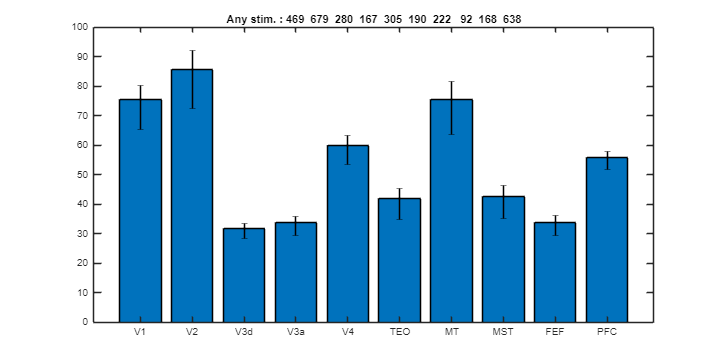

figure("Position", [0 0 2000 1000]);
cl = [0.9 0.1 0.1];
yt = zeros(1, 10);
st = zeros(1, 10);

for k = 1:10

    ths = median(mean(expvarz{k}, 2))*0;
    idxp = mean(expvarz{k}, 2) > ths;
    t = linspace(-500, 1000, 1500);
    yt(k) = max(abs(max(expvarz{k}(idxp, :) - mean(expvarz{k}(idxp, :), 'all'))))*100;
    st(k) = 5*max(std(expvarz{k}(idxp, :)))*100 / sqrt(min(100, sum(idxp)));
    
end

bar(areaNames, yt);                

hold on

er = errorbar(categorical(areaNames),yt,2*st,st);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';  
ylim([0 100]);

hold off
title("Any stim. : " + num2str(areaCounts));

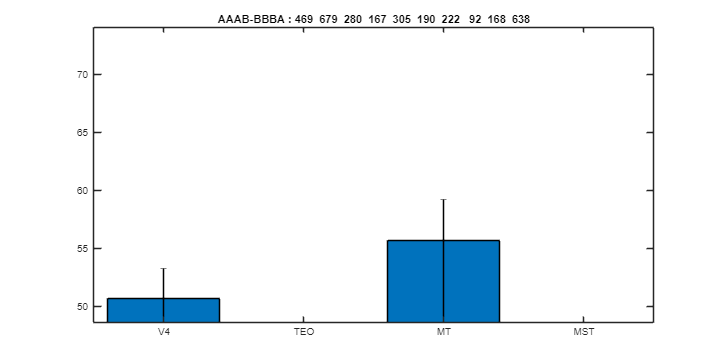

figure("Position", [0 0 2000 1000]);
cl = [0.9 0.7 0.7];
yt = zeros(1, 10);
st = zeros(1, 10);

for k = 1:10

    ths = median(mean(expvarz{k}, 2))*0;
    idxp = mean(expvarz{k}, 2) > ths;
    t = linspace(-500, 1000, 1500);
    yt(k) = mean(max(expvarz{k}(idxp, :) - mean(expvarz{k}(idxp, :), 'all')))*100;
    st(k) = 2 * max(std(expvarz{k}(idxp, :)))*100 / sqrt(min(100, sum(idxp)));
    
end

bar(areaNames,yt);                

hold on

er = errorbar(categorical(areaNames),yt,2*st,st);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';  

hold off
title("AAAB-BBBA : " + num2str(areaCounts));

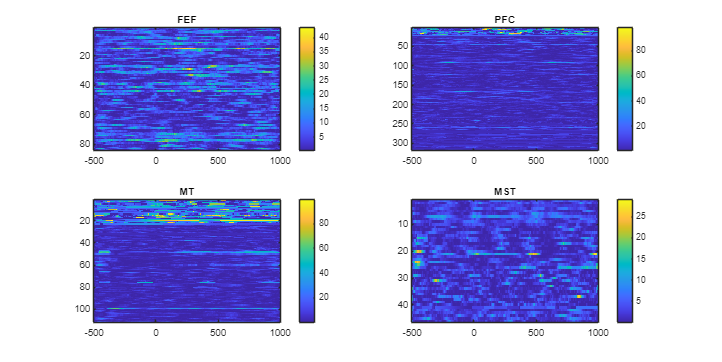

figure("Position", [0 0 2000 1000]);
% cl = [0.9 0.7 0.7];

for k = 7:10

    subplot(2, 2, mod(k-1, 4)+1);
    ths = median(mean(expvarz{k}, 2))*1;
    idxp = mean(expvarz{k}, 2) > ths;
    % figure("Position", [0 0 1500 500]);
    t = linspace(-500, 1000, 1500);
    yt = expvarz{k}(idxp, :)*100;
    imagesc(yt, "XData", t);colorbar();
    title(areaNames{k});

end